# **Gauntlet Challenge**

*Authors: Arturo Joya and Drew Pang*

For the Gauntlet Challenge, we went with level 1. Although we had most of the code was complete for each section leading up to level 3, putting each section together proved arduous. Various bugs prevented us from completing the whole challenge, so we reverted level 1.

Our strategy involved adapting previous work in the textbook and solution code to the Gauntlet Challenge to have the Neato reach the BoB. Although we ran into many problems, segmenting our code to ensure each section was running properly helped in resolving them.

### Collect Data from NEATO LiDAR Scans

Collect scans from four locations in the Gauntlet and export the data as a `r_all` and `theta_all` matrices. Scans are also saved in `gauntletScans.mat` such that code can be run outside of the simulator.

clear all; clf;

sub = rossubscriber('/scan');

% place Neato at the origin pointing in the ihat_G direction
placeNeato(1.9,-2.7,1,0)
pause(2);

% Collect data at the room origin
scan_message = receive(sub);
r_1 = scan_message.Ranges(1:end-1);
theta_1 = deg2rad([0:359]');

% place Neato at the origin pointing in a different direction
placeNeato(0,0,cos(pi/4),sin(pi/4))
pause(2);

% Collect data for the second location
scan_message = receive(sub);
r_2 = scan_message.Ranges(1:end-1);
theta_2 = deg2rad([0:359]');

% Place Neato at the third location
placeNeato(0,-2,1,0)
pause(2);

% Collect data for the third location
scan_message = receive(sub);
r_3 = scan_message.Ranges(1:end-1);
theta_3 = deg2rad([0:359]');

% Place Neato at the fourth location
placeNeato(1.9,-1,cos(pi),sin(pi))
pause(2);

% Collect data for the fourth location
scan_message = receive(sub);
r_4 = scan_message.Ranges(1:end-1);
theta_4 = deg2rad([0:359]');

% Collect all data into matrices
r_all = [r_1 r_2 r_3 r_4];
theta_all = [theta_1 theta_2 theta_3 theta_4];

% Save scans in a .mat file
save gauntletScans.mat theta_all r_all

### Convert LiDAR Scans into the Global Refrence Frame

Once we have LiDAR data from the Neato, we must convert it into data we can plot in the global refrence frame.

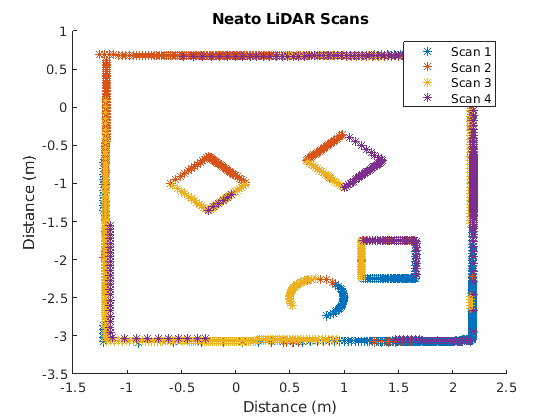

clear all; clf; hold on;
load gauntletScans.mat theta_all r_all

% Define Neato scan locations and angles
global_locations = [1.9, -2.7; 0, 0; 0, -2; 1.9, -1];
global_angles = [0; -pi/4; 0; pi];

% Define vector offset for the LiDAR sensor with relation to the Neato
lidar_offset = [-0.084, 0];

[L_frame_points N_frame_points G_frame_points] = deal(zeros(360,8));

% Convert LiDAR scans to cartesian
for i = 1:length(global_angles) 
    L_frame_points(:,[2*i-1 2*i]) = [r_all(:,i).*cos(theta_all(:,i)) r_all(:,i).*sin(theta_all(:,i))];
    N_frame_points(:,[2*i-1 2*i]) = L_frame_points(:,[2*i-1 2*i]) + lidar_offset;
    G_frame_points(:,[2*i-1 2*i]) = N_frame_points(:,[2*i-1 2*i])*[cos(global_angles(i)) -sin(global_angles(i)); sin(global_angles(i)) cos(global_angles(i))] + global_locations(i, :);
    plot(G_frame_points(:,2*i-1), G_frame_points(:,2*i), "*")
end

title("Neato LiDAR Scans")
xlabel("Distance (m)"); ylabel("Distance (m)")
legend({"Scan 1", "Scan 2", "Scan 3", "Scan 4"})

### Contour Plot Generation

Now that we have the scanned data, we can generate a contour. The following contour was generated with the known locations and sizes of the walls, obstacles, and BoB.

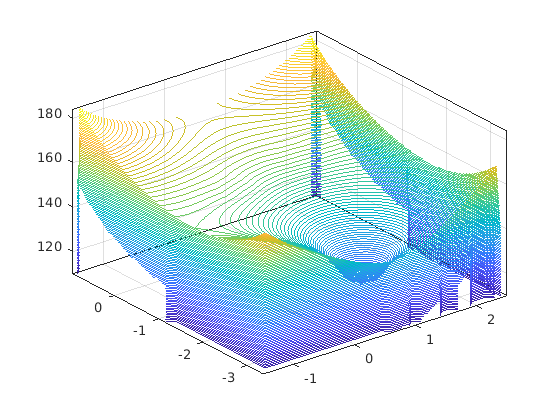

clf;
% Create meshgrid for contour
[xG, yG] = meshgrid(-1.5:0.1:2.5, -3.37:0.1:1);

[f, fx, fy] = deal(0);

% 0.2 was chosen as an arbitrary constant to get the contour to be steep
% enough. This constant is used to change the agressivness of the obstacle
% sources.
arbitrary_constant = 0.05;

% % Add sources for the walls
for i = -3.37:0.1:1
    f = f + log(sqrt((yG-i).^2 + (xG+1.5).^2)) + log(sqrt((yG-i).^2 + (xG-2.5).^2));
end
for i = -1.5:0.1:2.5
    f = f + log(sqrt((xG-i).^2 + (yG+3.37).^2)) + log(sqrt((xG-i).^2 + (yG-1).^2));
end

% Add sources for the obstacles
square_centers = [-0.25, -1; 1, -0.7; 1.41, -2];
for i = 1:length(square_centers)
    for theta = 0:0.4:2*pi
        a = 0.25*cos(theta) + square_centers(i,1);
        b = 0.25*sin(theta) + square_centers(i,2);
        f = f - arbitrary_constant*log(sqrt((xG-a).^2 + (yG-b).^2));
    end
end

% Add a sink for the BoB
for theta = 0:0.4:2*pi
    a = 0.25*cos(theta) + 0.75;
    b = 0.25*sin(theta) - 2.5;
    f = f + log(sqrt((xG-a).^2 + (yG-b).^2));
end

contour3(xG, yG, f, 100)
view([-38.0 37.7])

### Gradient Descent

Text

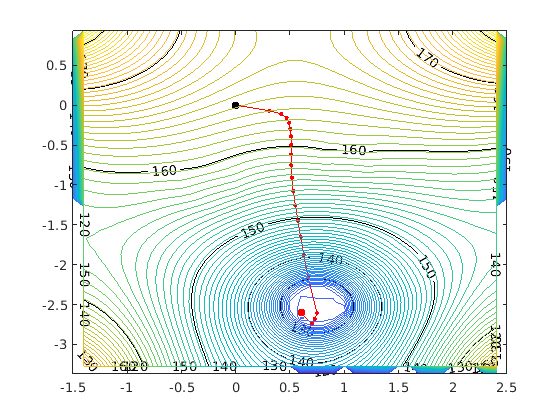

% Code
%initialize syms for the Neato to use based on the points fitted
%establish potential field equations
syms xN yN a b
poteq = log(sqrt((xN-a).^2 +(yN-b).^2));
fNeato = 0;
%global points
%[xG,yG]=meshgrid(-1.5:0.01:2.5,-3.37:0.01:1);
%[xG,yG]=meshgrid(-10:0.01:10,-10:0.01:10);

%Outline
for aO = -1.2:0.05:2.2
    fNeato = fNeato + subs(poteq,[a,b], [aO,0.7]) + subs(poteq,[a,b], [aO,-3.07]);
end
for bO = -3.07:0.05:0.7
    fNeato = fNeato + subs(poteq,[a,b], [-1.5,bO]) + subs(poteq,[a,b], [2.5,bO]);
end
% %Squares as circles
square_centers = [-0.25, -1; 1, -0.7; 1.41, -2]; 
for i = 1:length(square_centers)
    for t = 0:0.4:2*pi
        aC = square_centers(i,1) + 0.25*cos(t);
        bC = square_centers(i,2) + 0.25*sin(t);
        fNeato = fNeato - arbitrary_constant.*subs(poteq,[a,b], [aC,bC]);
    end
end
%BoB
for t = 0:0.4:2*pi
    aC = 0.75 + 0.25*cos(t);
    bC = -2.5 + 0.25*sin(t);
    fNeato = fNeato + subs(poteq,[a,b], [aC,bC]);
end
gradNeato = gradient(fNeato, [xN, yN]);

r_i = [0; 0];
delta = 0.9; % delta > 1 causes stepsize to grow; this prevents convergence
lam = 0.05;
tol = 1e-3;
n = 0;
n_max = 20;
grad_i = double(subs(gradNeato, {xN, yN}, {r_i(1), r_i(2)}));
R = [r_i];

% Run the algorithm
%R = gradient_ascend(gradNeato, r_0, delta, lambda_0, tolerance, n_max);
while (n < n_max) && (norm(grad_i)> tol)
    r_i = r_i - lam.*grad_i;
    grad_i = (double(subs(gradNeato, {xN, yN}, {r_i(1), r_i(2)})));
    lam = delta * lam;
    n = n + 1;
    R(:, end+1) = r_i;
end
clf
contour(xG,yG,f, 'k', 'ShowText', 'On')
hold on
contour3(xG, yG, f, 100)
view([0 90])
plot(R(1, :), R(2, :), "r")
plot(R(1, :), R(2, :), "r.", "MarkerSize", 10)
plot(R(1, 1), R(2, 1), "k.", "MarkerSize", 20)
plot(R(1, end), R(2, end), "r.", "MarkerSize", 20)

Running the Neato

%set up Neato
base = 0.235; %m
lambda = 0.05;
head = [1;0];
pos = [0;0];
NeatoPath = [0,0];

angSpeed = 0.2;  %rad/s (set higher than real to help with testing)
linSpeed = 0.5;  %m/s

%setup publisher
pub = rospublisher('/raw_vel');
sub_states = rossubscriber('/gazebo/model_states', 'gazebo_msgs/ModelStates');
msg = rosmessage(pub);
%stop robot
msg.Data = [0, 0];
send(pub, msg);
pause(2);

%place Neato at starting location
placeNeato(pos(1), pos(2), head(1), head(2));
pause(2);

reachedbob = false;
while ~reachedbob
    %get gradient of position (for descent
    gradVal = -double(subs(gradNeato, {xN, yN}, {pos(1), pos(2)}));
    crossProd = cross([head; 0], [gradVal; 0]);
    turnDir = sign(crossProd(3));
    turnAngle = asin(norm(crossProd)/(norm(head)*norm(gradVal)));
    turnTime = double(turnAngle) / angSpeed;
    msg.Data = [-turnDir*angSpeed*base/2,
                turnDir*angSpeed*base/2];
    send(pub, msg);
    startTurn = rostic;
    while rostoc(startTurn) < 1.16*turnTime
        pause(0.01);
    end
    head = gradVal;
    
    %act on robot
    fwdDist = norm(gradVal*lambda);
    fwdTime = fwdDist / linSpeed;
    msg.Data = [linSpeed, linSpeed];
    send(pub, msg);
    startFwd = rostic;
    while rostoc(startFwd) < 0.85*fwdTime
        nmsg = receive(sub_states);
        for j = 1 : length(nmsg.Name)
            if strcmp(nmsg.Name{j}, 'neato_standalone')
                posX = nmsg.Pose(j).Position.X;
                posY = nmsg.Pose(j).Position.Y;
            end
        end
        NeatoPath(end+1,:) = [posX, posY];
        pause(0.01)
    end
    % update position for the next iteration
    pos = pos + gradVal*lambda;
    reachedbob = fwdDist < 0.01;
end
msg.Data = [0, 0];
send(pub, msg);